
$$\begin{array}{l}
\mathrm{ECSE}\text{ }307-\mathrm{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\mathrm{Professor}\text{ }\mathrm{Aditya}\text{ }\mathrm{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\mathrm{TA}:\mathrm{Mohammad}\text{ }\mathrm{Afshari}\text{ }\mathrm{and}\text{ }\mathrm{Anas}\text{ }\mathrm{El}\text{ }\mathrm{Fathi}
\end{array}$$


# 
$$\begin{array}{l}
\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\mathrm{Lab}\text{ }2\\
\mathrm{Frequency}\text{ }\mathrm{Domain}\text{ }\mathrm{and}\text{ }\mathrm{Treansfer}\text{ }\mathrm{Functions}
\end{array}$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID   = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID   = '260743549';
%-------------------------------------------------------------------------%

## ***Objectives***

The purpose of this lab is to overview the basic MATLAB functions in linear systems and control. At the end of this lab, you will be able to plot the step and impulse response of a rational transfer function and analyze with first and second order transfer functions. 

## ***Introduction***

The first step in the design of a control system is to identify a mathematical model of the system. Such a mathematical model could be derived either from physical laws or from experimental data. For LTI systems, we only need to identify the impulse response or it's frequency-domain representation---the transfer function. In this lab, we introduce how to model transfer functions in MATLAB.

There are various methods to define a transfer function in \MATLAB. As an   example, suppose we have a system described by the following constant  coefficient linear differential equation:


$$a_2 \frac{d^2 y(t)}{dt} + a_1 \frac{d y(t)}{dt} + a_0 y(t) = b_1 \frac{d u(t)}{dt} + b_0 u(t)$$


We know that the transfer function of this system is


$$H(s) = \frac{Y(s)}{U(s)} = \frac{b_1 s + b_0}{a_2 s^2 + a_1 s + a_0}$$


Suppose $a_2 =1$$a_2 =1$, $a_1=3
$, $a_0 =2$, $b_1 =2$, $b_0 =2$.

The first method of specifying the function is to literally type out this expression. We first define the symbol $s$ using  the `tf` function and then define the transfer function $H$ in terms of $s$. For example:

        % Assign values to the coefficinets
        a2 = 1;
        a1 = 3;
        a0 = 2;
        b1 = 2;
        b0 = 6;
        % Define the transfer function
        s = tf('s') % Define s symbolically in frequency domain


s =
 
  s
 
Continuous-time transfer function.



Then we can directly define the transfer function as follows.

        H1 = (b1*s + b0) / (a2*s^2 + a1*s + a0)


H1 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



The second method is to directly specify the polynomials of the numerator and the denominators.   

        % Define the numinator
        num = [b1 b0];
        % Define the nenuminator
        den = [a2 a1 a0];
        % Define the transfer function
        H2 = tf(num, den)


H2 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



There are various other forms of defining the transfer function. Run

        doc tf % MATLAB Help for tf

to view the complete documentation of the transfer function.

Another way to define the transfer function is to use the gain, poles and zeros. Let's reconsider the above transfer function in pole-zero form.


$$H\left(s\right)=2\frac{s+3}{\left(s+1\right)\left(s+2\right)}$$
 

We can specify the transfer function in the pole zero form using the following code.

        k = 2;           % The gain
        z = [ -3 ];      % The set of zeros
        p = [-1 -2];     % The set of poles
        H3 = zpk(z,p,k)  % Define the transfer function


H3 =
 
    2 (s+3)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



There are other forms of using the `zpk` function. Run

        doc zpk

to view the complete documentation of the `zpk` function. It is possible to identify the poles and zeros of a **rational** transfer function using `tf2zp`:

        [z,p,k] = tf2zp(num,den)

z = -3

p =     -2
    -1


k = 2

## *Plotting Impulse and Step Responces*

To plot the impulse response of a transfer function, one can use `impulse(system)`; to plot the step response, one can use `step(system)`. As an example, we plot the impulse and step responses of the system defined in the previous section:

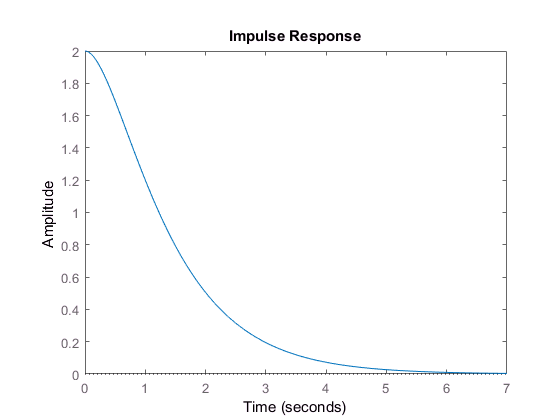

        impulse(H1)

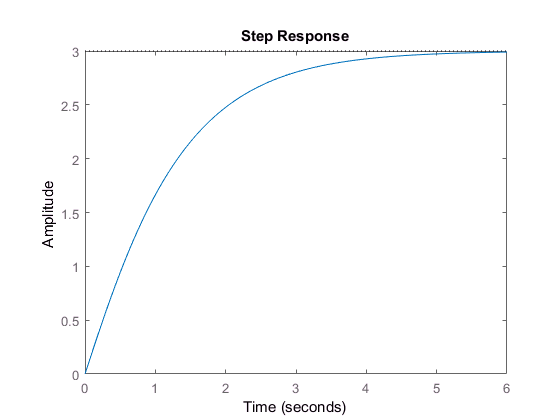

        step(H1)

There are other forms of both the `impulse` and `step `functions. For example, `impulse(system,Tfinal)` plots the impulse response from $t=0$ to $t=T$.

        T = 10                   % Final time value

T = 10

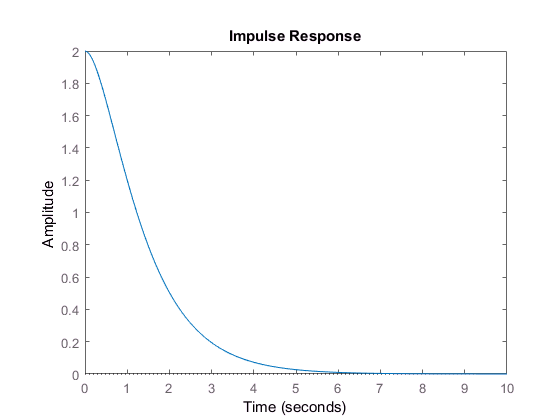

        impulse(H1, T)

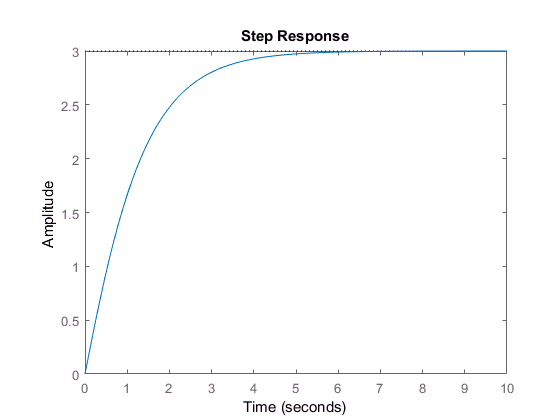

        step(H1,T)

Run

        doc impulse
        doc step

to view the complete documentation of the `impulse `and` step` functions. 

To find the poles and zeros of a transfer function, use `pole(system)` and `zero(systems)`. To plot the pole-zero plot, use `pzplot(system)`. For example, for the system defined above, the poles are

        pole(H1)

ans =     -2
    -1


and the zeros are

        zero(H1)

ans = -3

We can plot the pole-zero plot using

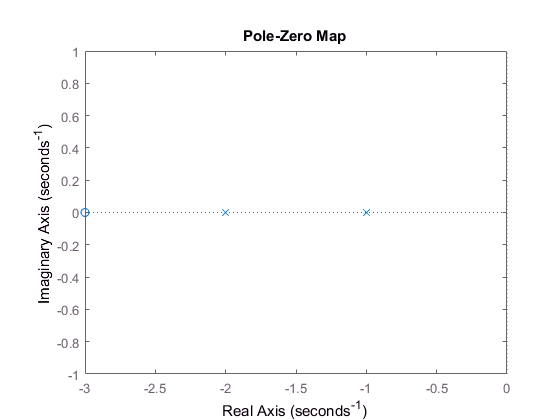

pzplot(H1)

**Interconnecting systems**

To get the transfer function for two systems connected in feedback, use

        H = feedback(H1,H2)  % Feedback or closed loop interconnection of systems


H =
 
     2 s^3 + 12 s^2 + 22 s + 12
  --------------------------------
  s^4 + 6 s^3 + 17 s^2 + 36 s + 40
 
Continuous-time transfer function.



## *System Response characteristics*

Consider the following step response of an unknown transfer function.

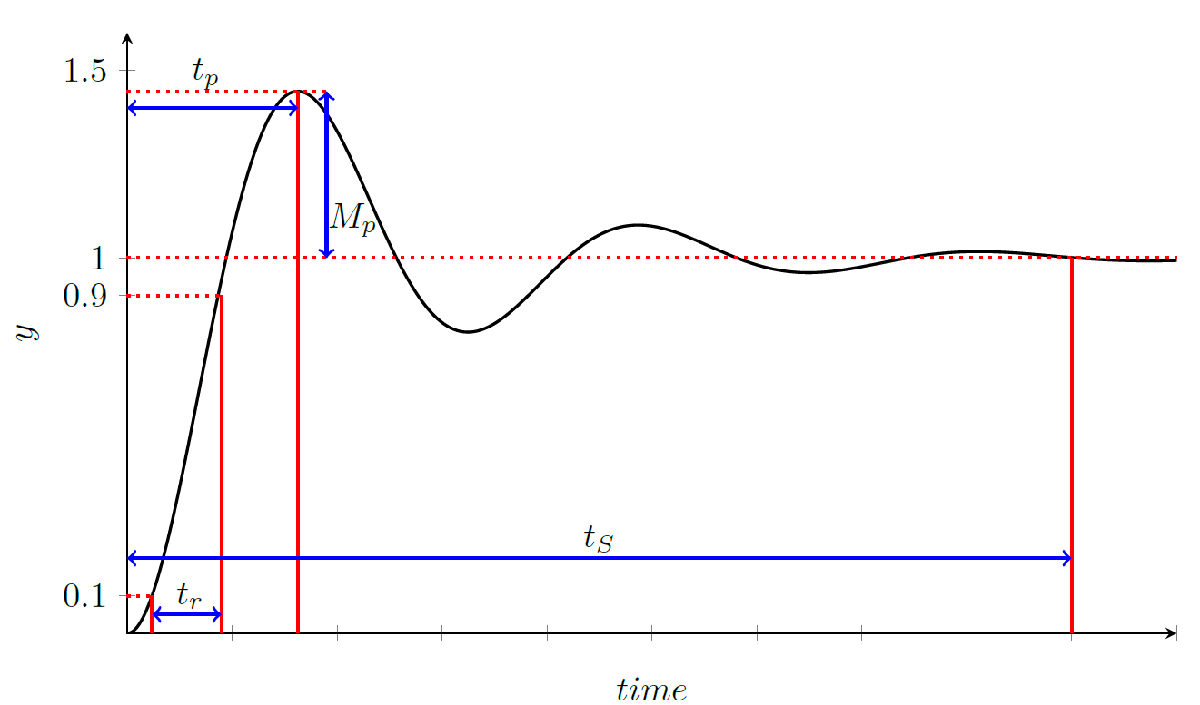

Depending on the location of the zeros and poles in a tranfer function, it is possible to define a system response by the following characteristics:

- Rise time $\left(t_r \right)$: is the time it takes the system to reach to rise from 10% to 90% of its final value. 

- Peak time $\left(t_p \right)$: is the time until the response hits its maximum overshoot.

- Overshoot $\left(M_p \right)$: is the peak value of the step response of the system. 

- Settling time $\left(t_s \right)$: is the time for the response to settle within $\pm \text{ }\Delta %$ of its final value. 

It is possible to find these values in Matlab given a transfer function. `stepinfo(system)` computes the step-response characteristics for a dynamic system model. For example

       stepinfo(H1)

ans = struct with fields:
        RiseTime: 2.4200
    SettlingTime: 4.1960
     SettlingMin: 2.7023
     SettlingMax: 2.9974
       Overshoot: 0
      Undershoot: 0
            Peak: 2.9974
        PeakTime: 7.3222


## *Question 1 (2 marks)*

In this question, you have to plot the step response **(for 25 sec)** and identify the characteristics of the transient response of the following system


$$G\left(s\right)=\frac{1}{\text{ }s^2 +2\xi \text{ }s+1}$$


for $\xi =\left\lbrace 0\ldotp 25,0\ldotp 75,1,2\right\rbrace$.

       % Enter your code here
      num = 1;
      den = [1 0.5 1];
      T = 25;
      G1 = tf(num,den)


G1 =
 
         1
  ---------------
  s^2 + 0.5 s + 1
 
Continuous-time transfer function.



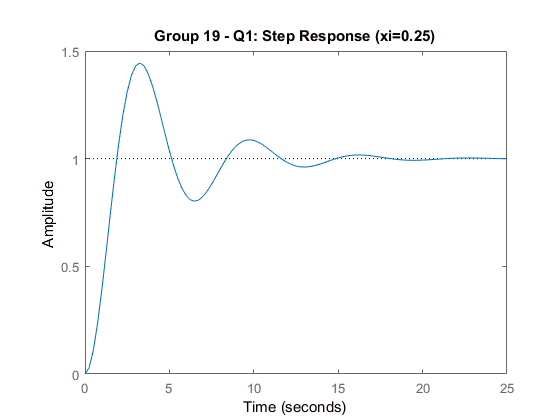

      step(G1,T);
      title('Group 19 - Q1: Step Response (xi=0.25)')

      stepinfo(G1)

ans = struct with fields:
        RiseTime: 1.2687
    SettlingTime: 14.1159
     SettlingMin: 0.8027
     SettlingMax: 1.4432
       Overshoot: 44.3235
      Undershoot: 0
            Peak: 1.4432
        PeakTime: 3.3157


      
      num = 1;
      den = [1 1.5 1];
      T = 25;
      G2 = tf(num,den)


G2 =
 
         1
  ---------------
  s^2 + 1.5 s + 1
 
Continuous-time transfer function.



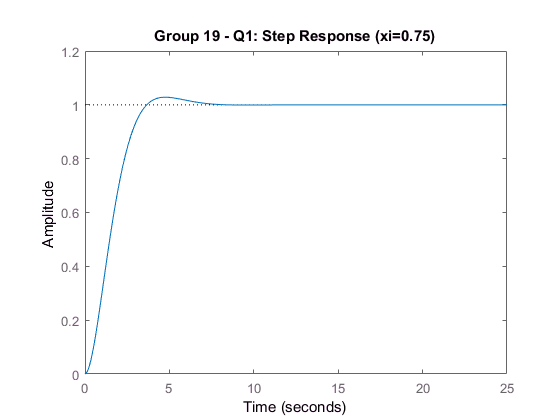

      step(G2,T);
      title('Group 19 - Q1: Step Response (xi=0.75)')

      stepinfo(G2)

ans = struct with fields:
        RiseTime: 2.2884
    SettlingTime: 5.7426
     SettlingMin: 0.9049
     SettlingMax: 1.0284
       Overshoot: 2.8369
      Undershoot: 0
            Peak: 1.0284
        PeakTime: 4.7280


      
      num = 1;
      den = [1 2 1];
      T = 25;
      G3 = tf(num,den)


G3 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



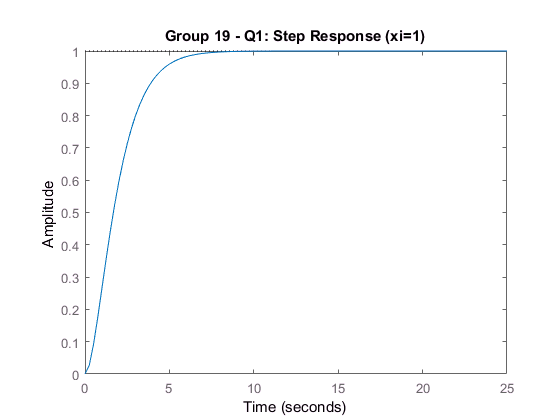

      step(G3,T);
      title('Group 19 - Q1: Step Response (xi=1)')

      stepinfo(G3)

ans = struct with fields:
        RiseTime: 3.3579
    SettlingTime: 5.8339
     SettlingMin: 0.9000
     SettlingMax: 0.9994
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9994
        PeakTime: 9.7900


      
      num = 1;
      den = [1 4 1];
      T = 25;
      G4 = tf(num,den)


G4 =
 
        1
  -------------
  s^2 + 4 s + 1
 
Continuous-time transfer function.



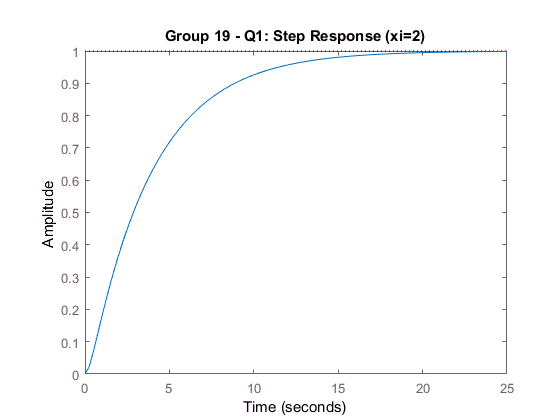

      step(G4,T);
      title('Group 19 - Q1: Step Response (xi=2)')

      stepinfo(G4)

ans = struct with fields:
        RiseTime: 8.2308
    SettlingTime: 14.8789
     SettlingMin: 0.9017
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 27.3269


## *Question 2 (4 marks)*

Consider the following open loop unstable system. 


$$Q\left(s\right)=\frac{s+1}{s\left(s-1\right)\left(s+6\right)}$$


A constant controller $k$is used to stablize this system. For different values of $k\in \left\lbrace 10,20,50,100\right\rbrace$plot the step response **(for 15 seconds)** of the closed loop controlled system and measure the output components using `stepinfo `function.

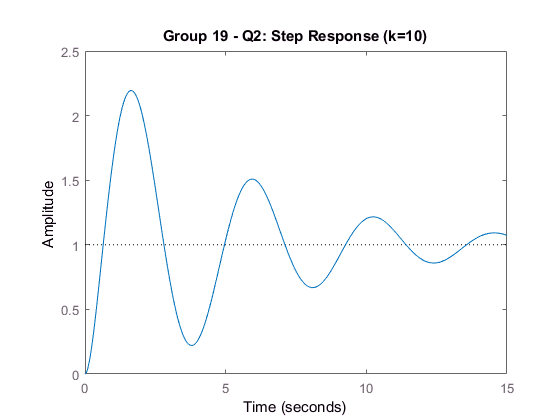

         % Enter your code here
         % Define the transfer function
         T = 15;
         Q = (s+1)/(s*(s-1)*(s+6));
         
         % k=10
         k = 10;
         Q1 = feedback(k*Q,1);
         step(Q1,T);
         title('Group 19 - Q2: Step Response (k=10)')

         stepinfo(Q1)

ans = struct with fields:
        RiseTime: 0.4424
    SettlingTime: 21.2506
     SettlingMin: 0.2212
     SettlingMax: 2.1939
       Overshoot: 119.3930
      Undershoot: 0
            Peak: 2.1939
        PeakTime: 1.6408


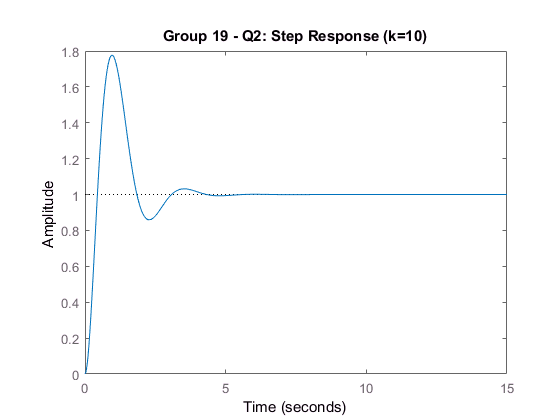

         
      
         
         % k=20
         k = 20;
         Q2 = feedback(k*Q,1);
         step(Q2,T);
         title('Group 19 - Q2: Step Response (k=10)')

         stepinfo(Q2)

ans = struct with fields:
        RiseTime: 0.2989
    SettlingTime: 3.8974
     SettlingMin: 0.8592
     SettlingMax: 1.7772
       Overshoot: 77.7158
      Undershoot: 0
            Peak: 1.7772
        PeakTime: 0.9644


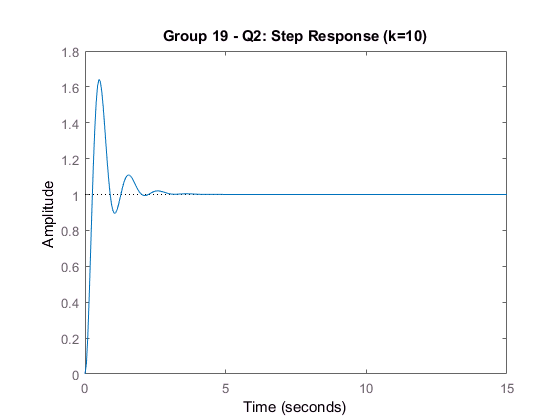

         
         % k=50
         k = 50;
         Q3 = feedback(k*Q,1);
         step(Q3,T);
         title('Group 19 - Q2: Step Response (k=10)')

         stepinfo(Q3)

ans = struct with fields:
        RiseTime: 0.1767
    SettlingTime: 2.6377
     SettlingMin: 0.8948
     SettlingMax: 1.6430
       Overshoot: 64.3033
      Undershoot: 0
            Peak: 1.6430
        PeakTime: 0.5062


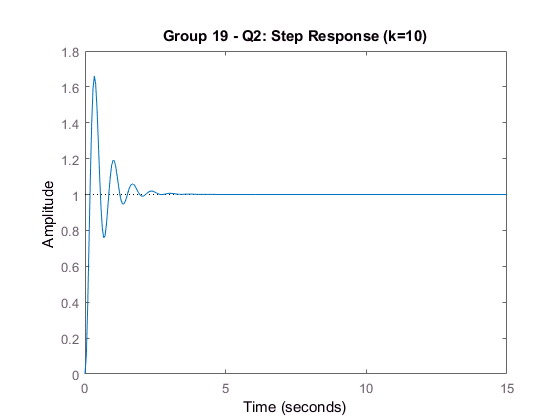

         
         % k=100
         k = 100;
         Q4 = feedback(k*Q,1);
         step(Q4,T);
         title('Group 19 - Q2: Step Response (k=10)')

         stepinfo(Q4)

ans = struct with fields:
        RiseTime: 0.1190
    SettlingTime: 1.8674
     SettlingMin: 0.7606
     SettlingMax: 1.6607
       Overshoot: 66.0662
      Undershoot: 0
            Peak: 1.6607
        PeakTime: 0.3303


## *Question 3 (4 marks)*

Consider the closed loop transfer function in Question 2. For $k=\left\lbrace 10,20\right\rbrace$, construct a second order system of the form


$$G\left(s\right)=\frac{\frac{k}{\text{ }{|p}_3 |}\left(s+z_1 \right)}{\text{ }\left(s+p_1 \right)\left(s+p_2 \right)}$$


where $p_1$ and $p_2$ are the dominant poles (i.e., poles with the largest real values) and $p_3$ is the ineffective pole(i.e., the pole with the smallest real value). Plot the step response of $G\left(s\right)$ for **15 sec** and measure the output components using `stepinfo`.

         % Enter your code here
         % Find the poles of the two transfer functions
         T = 15;
         
         pole(Q1)

ans =   -4.6030 + 0.0000i
  -0.1985 + 1.4605i
  -0.1985 - 1.4605i


         pole(Q2)

ans =   -1.2107 + 2.5081i
  -1.2107 - 2.5081i
  -2.5786 + 0.0000i


         % Transfer functions with dominant poles
         
         % k=10
         G1 = ((10/(4.6030))*(s+1))/((s+0.1985+1.4605i)*(s+0.1985-1.4605i))


G1 =
 
     2.172 s + 2.172
  ---------------------
  s^2 + 0.397 s + 2.172
 
Continuous-time transfer function.



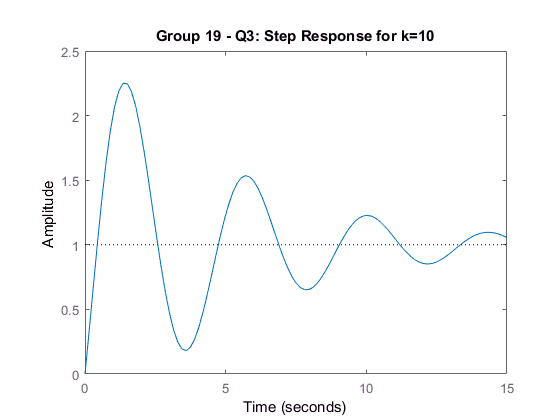

         step(G1,T)
         title('Group 19 - Q3: Step Response for k=10')

         stepinfo(G1)

ans = struct with fields:
        RiseTime: 0.3487
    SettlingTime: 21.0232
     SettlingMin: 0.1824
     SettlingMax: 2.2498
       Overshoot: 124.9801
      Undershoot: 0
            Peak: 2.2498
        PeakTime: 1.4920


         
         % k=20
         G2 = ((20/(2.5786))*(s+1))/((s+1.2107+2.5081i)*(s+1.2107-2.5081i))


G2 =
 
     7.756 s + 7.756
  ---------------------
  s^2 + 2.421 s + 7.756
 
Continuous-time transfer function.



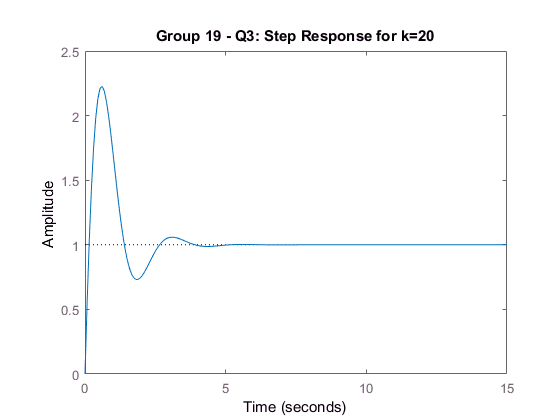

         step(G2,T)
         title('Group 19 - Q3: Step Response for k=20')

         stepinfo(G2)

ans = struct with fields:
        RiseTime: 0.1163
    SettlingTime: 3.6016
     SettlingMin: 0.7308
     SettlingMax: 2.2266
       Overshoot: 122.6670
      Undershoot: 0
            Peak: 2.2266
        PeakTime: 0.6086


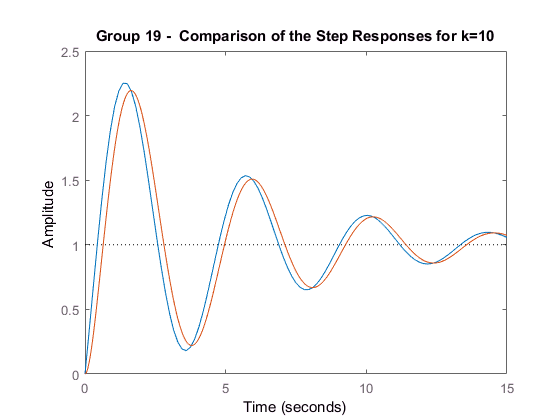

         
         % Comparison part
         step (G1, Q1,T);
         title('Group 19 -  Comparison of the Step Responses for k=10')

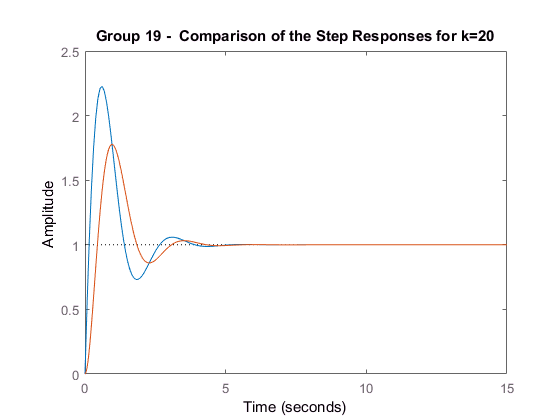

      
         step (G2, Q2,T);
         title('Group 19 -  Comparison of the Step Responses for k=20')

***Compare the responses with those obtained in Question 2 here:***

*When the gain is equal to 10, the transiant response of Q1 and G1 have very similar signals with a very small phase shift. Whereas when the gain is equal to 20, the transiant response of Q2 and G2 is slightly shifted to the right with a smaller amplitude because the least dominant pole has a very small effect (because further away from the origin).*